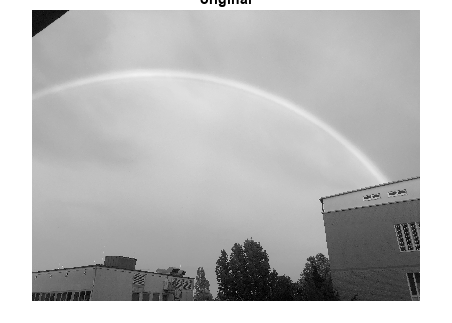

clear
img = imread('E:\Matlab数字图像处理程序\IMG_4208.jpg');

[R,G,B]=imsplit(img);

grayimage = rgb2gray(img);

figure()



imshow(grayimage);
title('original')

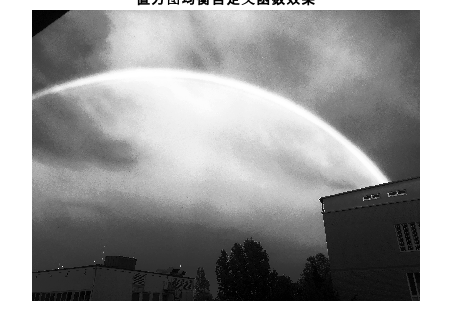


[rownumber,columnnumber,pages]=size(img);

grayscalenum = zeros(1,256);

for i = 0:1:255
    for row = 1:rownumber
        for column = 1:columnnumber
            if grayimage(row,column) == i
                grayscalenum(i+1) = grayscalenum(i+1) + 1;
            end
        end
    end
end

pixelamount = rownumber * columnnumber;

newgrayscale = zeros(1,256);


b=255;
a=0;

for i = 0:1:255
    for j = 0:1:i
        newgrayscale(i+1) = (b-a) * (sum(grayscalenum(1:(j+1))))/pixelamount;
    end
end



for row = 1:rownumber
    for column = 1:columnnumber
        grayimage(row,column) = newgrayscale(grayimage(row,column)+1);
    end
end

figure()

imshow(grayimage)
title('直方图均衡自定义函数效果')